# Notebook 5: Data and Fitting

*Author:* Zachary del Rosario, Fall 2020

*Learning Objectives:* As a result of reading this notebook, you will learn:

- How to read data into Matlab

- How to compare simulations against data

- Some tips for testing model sensitivity

## Fitting a Model with Data

In the previous notebook we made arbitrary choices for $\beta, \gamma$, which is fine for *testing *a model. However, we can't simply make arbitrary choices if we're trying to use a model to describe reality. We need to *fit* our model's parameters $\beta, \gamma$ by studying real data. *Fitting*a model means adjusting its inputs to best-represent a physical scenario. Often we want to do this to make predictions or to support design decisions. Let's consider a specific scenario to make this more concrete:

### Scenario

Let's imagine we're in the middle of cold season: We're living in a fairly small community and we've noticed that a number of folks have come down with the flu. We're in week six of flu season, and we're interested in how much longer it's going to last. 

- The total population is 100 persons.

- At Week 0 *some number* of persons have the flu.

- From tracking sick individuals, we've noticed that people tend to recover from this flu in two weeks.

- It's Week 6, and we've surveyed everyone in the 100-person community; we have a record of how many people were sick in each week.

We're interested in answering the following questions:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

The following code loads data from this scenario and plots it over time.

% Load the data
tab_data = readtable("infected.csv", "Delimiter", ",")

tab_data = 7×2 table
    i     week
    __    ____

     2     0  
     3     1  
     5     2  
     8     3  
    11     4  
    16     5  
    20     6  


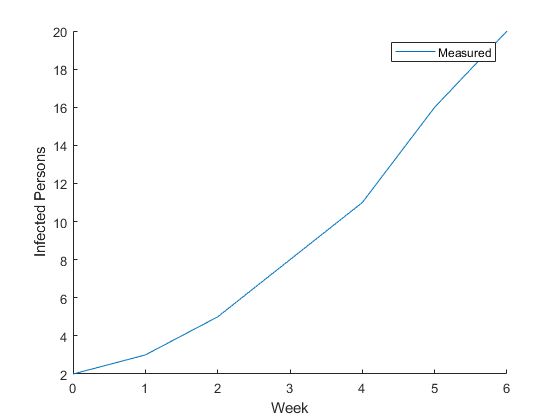


% Plot the data
figure(1); clf; hold on;
plot(tab_data.week, tab_data.i); label1 = "Measured";

xlabel("Week")
ylabel("Infected Persons")
legend({label1})

**Exercise:** Take a look at `tab_data`; what do you notice about the values that `tab_data.i` take?

## Fitting Parameters

Since we have information about a scenario, we can try to fit a model to our available data. Let's compare the simulation results from the previous notebook. How well do arbitrary choices for $\beta, \gamma$ and the initial number of infected `tab_state.i` match the data?

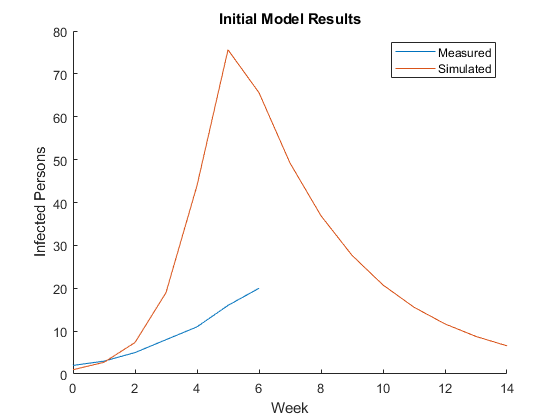

% Define parameters
beta = 1 / 50; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 4; % Recovery rate (1 / day)
% Set up system
tab_state = fcn_make_table( ...
    "s", 99, ...
    "i", 1, ...
    "r", 0 ...
);
tab_system = fcn_make_table("beta", beta, "gamma", gamma);

% Run simulation
tab_record = fcn_simulate(tab_state, tab_system, 20);

% Plot the data
figure(2); clf; hold on;
plot(tab_data.week, tab_data.i); label1 = "Measured";
plot(tab_record.week, tab_record.i); label2 = "Simulated";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Initial Model Results")

**Exercise:** Compare the measured and simulated curves. What is similar about them? What is different? What simulation settings might need tweaking?

*Solution:* From the results at Week 0, we can see the simulation starts with the wrong number of initially-infected people. The infection rate is also much faster in the simulation, as evidenced by the steeply-increasing curve. Thus the simulation peaks much sooner than the measured case, which has not yet crested. We'll need to adjust `beta, gamma, i0`.

Before we go randomly-changing model parameters, we should first get a handle on *model sensitivity*.

### Model sensitivity

All models are *sensitive---*to some degree or another---to their inputs; for instance, our SIR model results change with changes to the parameters $\beta, \gamma$ and starting conditions `s, i, r`. Before we go randomly-changing these values in an attempt to fit data, we should first build a *mental model* for how changing the inputs changes the simulation results. We should build intuition for the model sensitivity.

The following code slightly tweaks the value of $\gamma$, re-runs the simulation, and compares the baseline and tweaked model results.

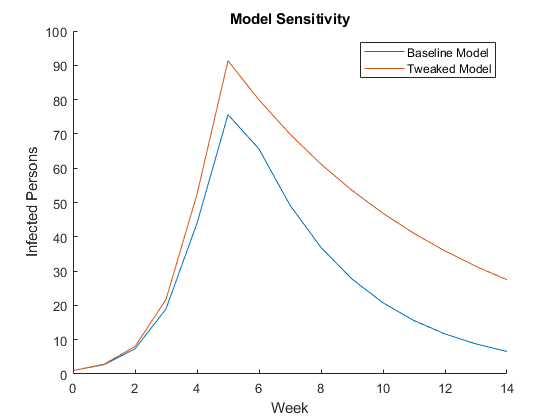

% Define parameters
beta = 1 / 50; % Baseline: beta = 1 / 50
gamma = 1 / 8; % Baseline: gamma = 1 / 4
i0 = 1;        % Baseline: i0 = 1

% Set up system
tab_state = fcn_make_table( ...
    "s", 100 - i0, ...
    "i", i0, ...
    "r", 0 ...
);
tab_system = fcn_make_table("beta", beta, "gamma", gamma);

% Run simulation
tab_tweaked = fcn_simulate(tab_state, tab_system, 20);

% Plot the data
figure(3); clf; hold on;
plot(tab_record.week, tab_record.i); label1 = "Baseline Model";
plot(tab_tweaked.week, tab_tweaked.i); label2 = "Tweaked Model";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Model Sensitivity")

**Exercise:** Systematically adjust the values of $\beta, \gamma$ and `i0. `Record what each value *physically represents*, and document how changing their values tend to affect model results. Which of $\beta, \gamma$ and `i0` tends to *most dramatically* change the results? Which tends to *least dramatically* change the results?

- $\beta$ represents _______: Increasing $\beta$ tends to _________

- $\gamma$ represents _______: Increasing $\gamma$ tends to _________

- `i0` represents _______: Increasing `i0` tends to _________

*Solution:* 

- $\beta$ represents the infection rate: Increasing $\beta$ tends to steepen the curve, leading to a larger number of infected persons.

- $\gamma$ represents the recovery period: Increasing $\gamma$ tends to broaden the curve of infections and lead to a larger number of infected persons.

- `i0` represents the initial count of infected persons: Increasing `i0` tends to shift the curve without changing the total quite so much. `i0 `seems to be the least sensitive parameter.

### Principled Model Fitting

Now that we have some physical understanding of our model inputs $\beta, \gamma$ and `i0`, we can do some *principled* model fitting. First, we'll use our physical understanding of the inputs to try to set some of them directly. Then we'll use the data to try to set the remaining parameters.

**Direct Setting**: We know from the scenario how many people were infected at Week 0; it's in our dataset!

% Look at week zero
tab_data(tab_data.week == 0, :)

ans = 1×2 table
    i    week
    _    ____

    2     0  


Thus we can set `i0 = 2` directly!

Also, we know from data collection some information about the *recovery period*; remember the scenario stated

> "From tracking sick individuals, we've noticed that people tend to recover from this flu in two weeks."

Since $\gamma$ is equal to `1 / recovery_period` (See `notebook04.mlx`), we can set `gamma = 1 / 2`.

**Fitting simulation to data:** The parameter $\beta$ is a bit trickier to set; we can't set it directly based on the information we have. However, we can compare simulation results against data, and use that information to help set $\beta$.

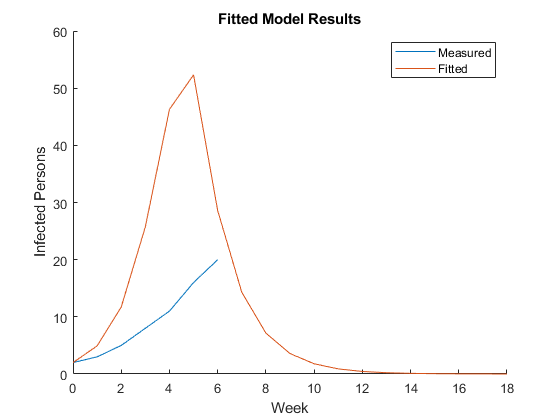

% TODO: Fit this parameter
beta = 1 / 50; % Infection rate (New / Susceptible / Infected / day)

% NOTE: We fit these parameters directly in the steps above
gamma = 1 / 2; % Recovery rate (1 / day)
% Set up system
tab_state = fcn_make_table( ...
    "s", 98, ...
    "i", 2, ...
    "r", 0 ...
);
tab_system = fcn_make_table("beta", beta, "gamma", gamma);

% Run simulation
tab_fitted = fcn_simulate(tab_state, tab_system, 20);

% Plot the data
figure(4); clf; hold on;
plot(tab_data.week, tab_data.i); label1 = "Measured";
plot(tab_fitted.week, tab_fitted.i); label2 = "Fitted";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Fitted Model Results")

**Exercise: **Manually fit the $\beta$ parameter by comparing the simulation results against data Remember the exercise you did above: Keep in mind how changing $\beta$ tends to change the simulation results. What is the best-fit value for $\beta$ that you found?

*Solution*: The data were generated with `beta = 1 / 90`; that should be the best-fit value.

## Using the Model

Congratulations, you just fit your first model! Now that we have a fitted model, we can use it to *make predictions*. Remember that we only have data up through Week 6. We can use the model to make a prediction about future weeks.

**Exercise:** Use your fitted model along with plotting or table inspection to answer the following questions:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

*Solution:*

% NOTE: These are the ground-truth parameter settings
tab_state_true = fcn_make_table( ...
    "s", 98, ...
    "i", 2, ...
    "r", 0 ...
);
tab_system_true = fcn_make_table("beta", 1 / 90, "gamma", 1 / 2);

describe(tab_true)

ans = 6×5 table
      s         i         r       week       stat  
    ______    ______    ______    _____    ________

        98    22.727    88.557       20    "Max"   
    72.524    15.512    86.307    15.25    "Q3"    
    39.542    8.4436    52.015       10    "Mean"  
    19.691    5.0105    64.765       10    "Median"
    11.823    1.8254    13.058     4.75    "Q1"    
    11.242    0.2011         0        0    "Min"   


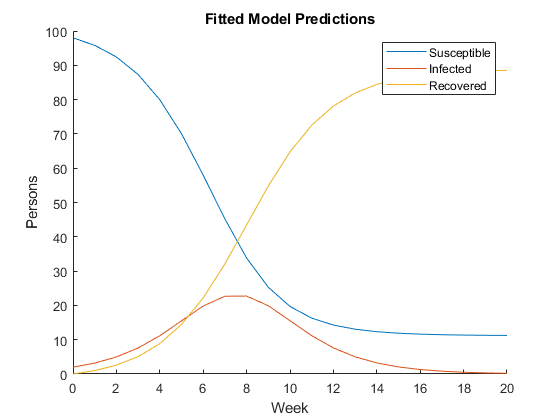


% Run simulation
tab_true = fcn_simulate(tab_state_true, tab_system_true, 20);
% Plot the fitted simulation
figure(5); clf; hold on;
plot(tab_true.week, tab_true.s); label1 = "Susceptible";
plot(tab_true.week, tab_true.i); label2 = "Infected";
plot(tab_true.week, tab_true.r); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("Fitted Model Predictions")

- When will this flu season be over? *By Week 14 the number of Susceptible persons will be stable; this is a good indication that the flu season will be over.*

- How many of the 100 total persons will fall ill with the flu?* The minimum value of Susceptible reaches around 11, so about 89 of 100 persons will ultimately be infected.*